# AM_main

## 定义参数

Am=2;%振幅
Fs=1000;%分辨率
dt=1/Fs;
fm=40;
fc=100;
t=0:dt:0.3;

## AM调制

m_t=sin(2*pi*fm*t);
AM=AM_modulation(Am,m_t,fc,t);

## 观察AM调制频谱

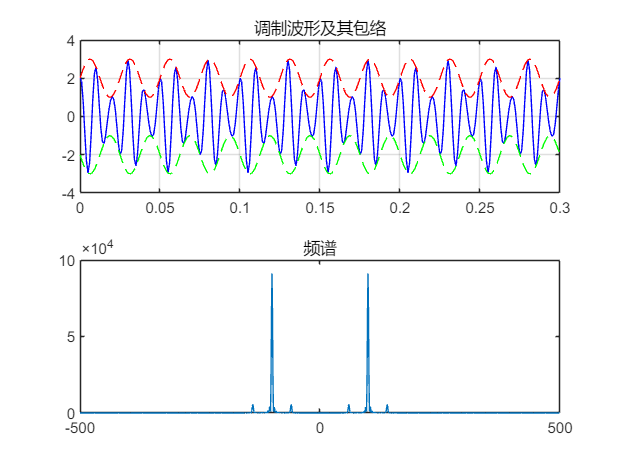

[freq,spec]=analyze_spectrum(AM,Fs,1000);
figure(1);
subplot(2,1,1);plot(t,AM,'b');title('调制波形及其包络');
hold on;
plot(t,Am+m_t,'r--');
plot(t,-Am-m_t,'g--');
grid;hold off;
subplot(2,1,2);plot(freq,spec);title('频谱');

## 通过信道

received_signal = channel_simulation(AM, 40, fc, Fs);

## AM相干解调

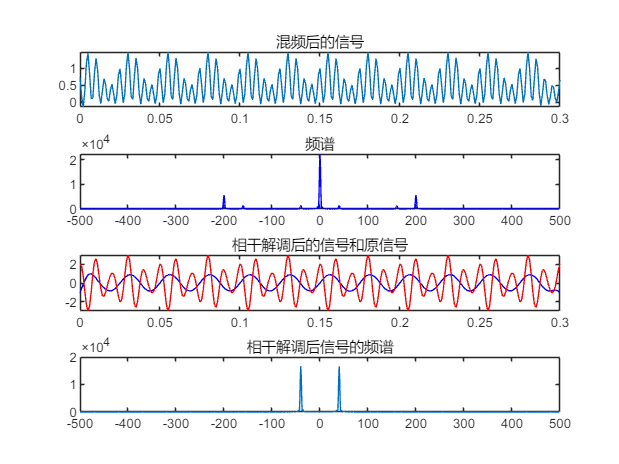

[m_t,mix_t] = Coherent_Demodulation(received_signal,t,fc,Fs);
[freq,spec_m]=analyze_spectrum(mix_t,Fs,1000);
[freq,spec_b]=analyze_spectrum(m_t,Fs,1000);
figure(2);
subplot(4,1,1);plot(t,mix_t);title('混频后的信号');% 调制信号与载波信号相乘
subplot(4,1,2);plot(freq,spec_m,'b');title('频谱');
subplot(4,1,3);plot(t,m_t,'b');hold on;plot(t,AM,'r');hold off;title('相干解调后的信号和原信号');
subplot(4,1,4);plot(freq,spec_b);title('相干解调后信号的频谱');

## AM非相干解调

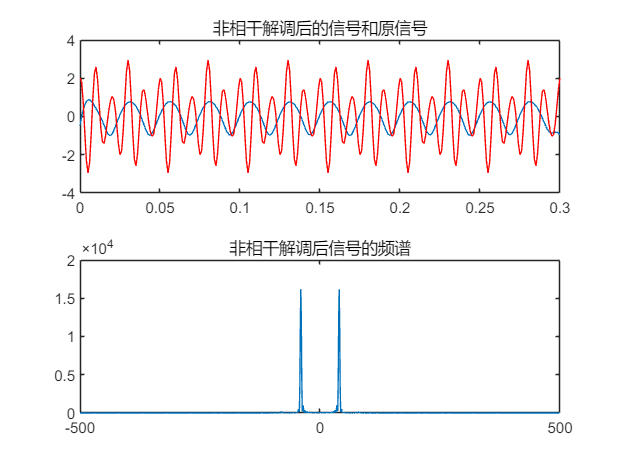

[m_t_nc,mix_t_nc] = Noncoherent_Demodulation(received_signal,fc,Fs);
[freq,spec_b]=analyze_spectrum(m_t_nc,Fs,1000);
figure(3);
subplot(2,1,1);plot(t,m_t_nc);hold on;plot(t,AM,'r');hold off;title('非相干解调后的信号和原信号');
subplot(2,1,2);plot(freq,spec_b);title('非相干解调后信号的频谱');